### 3. Βελτίωση εικόνας - Φιλτράρισμα Θορύβου 

1) Αφού φορτώσουμε την εικόνα x προσθέτουμε λευκό Gaussian θόρυβο μηδενικής μέσης τιμής και τέτοιας διασποράς ώστε η τελική εικόνα να έχει λόγο σήματος προς θόρυβο ίσο με 15 dB. Χρησιμοποιούνται οι συναρτήσεις imnoise() ,  παρακάτω φαίνονται οι δύο εικόνες η αρχική και η εικόνα με τον επιπρόσθετο λευκο gaussian θόρυβο.Εφαρμόζονται τα φίλτρα και φαίνονται τα αποτελέσματα.

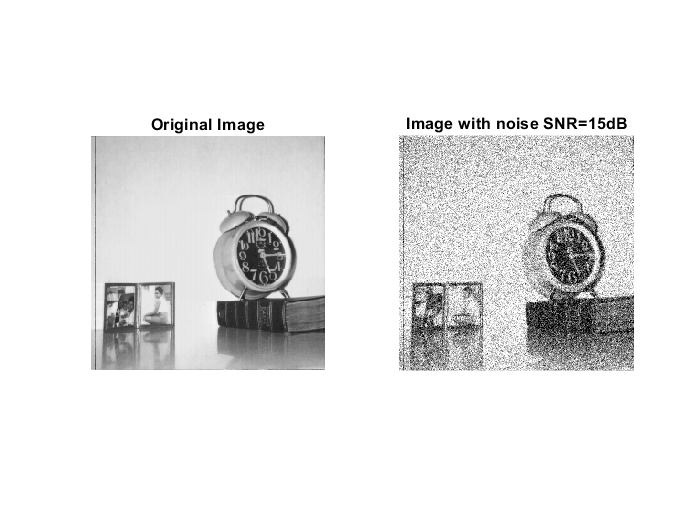

clc
clear all

x = imread('images\3\clock.tiff');
m=0;
snr=15;
var_gauss=10^(-snr/10);
x_with_noise=imnoise(x,'gaussian',m,var_gauss);
%theloume na xrhsimopoihsoume median filter kai moving average filter gia
%na afairesoume leuko thoruvo
figure();
subplot(1,2,1);
imshow(x);
title("Original Image");
subplot(1,2,2);
imshow(x_with_noise);
title(sprintf("Image with noise SNR=%ddB",snr));

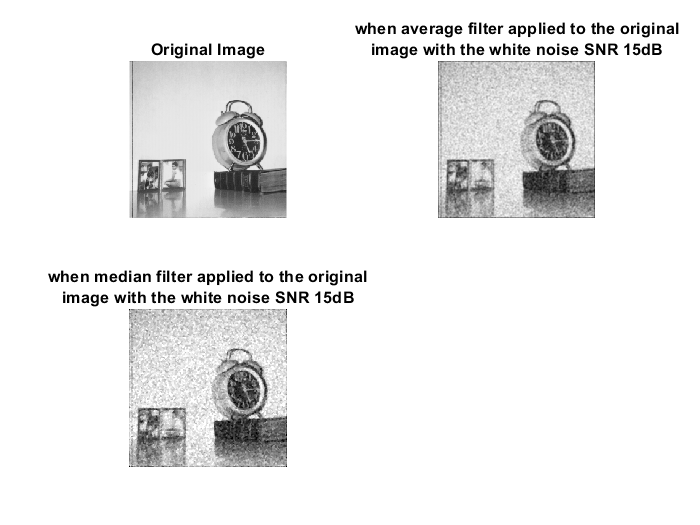

x_with_noise_augmented=zeros(258,258);
x_with_noise_augmented(2:257,2:257)=x_with_noise;
[N1,N2]=size(x_with_noise_augmented);

x_average=zeros(256,256);
x_median=zeros(256,256);
for i=1:N1-2
    for j=1:N2-2
        kernel=x_with_noise_augmented(i:i+2,j:j+2);
        kernel_average=mean(kernel,'all');
        kernel_median=median(kernel,'all');
        x_average(i+1,j+1)=kernel_average;
        x_median(i+1,j+1)=kernel_median;
    end
      
end
x_average=uint8(x_average(2:257,2:257));
x_median=uint8(x_median(2:257,2:257));


figure();
subplot(2,2,1);
imshow(x);
title("Original Image");
subplot(2,2,2);
imshow(x_average);
title({"when average filter applied to the original";"image with the white noise SNR 15dB"})
subplot(2,2,3);
imshow(x_median);
title({"when median filter applied to the original" ; " image with the white noise SNR 15dB "})

2)2) Στην εικόνα clock.tiff προσθέτουμε κρουστικό θόρυβο σε ποσοστό 20% και χρησιμοποιούμε τα ίδια φίλτρα για την αφαίρεση του θορύβου.

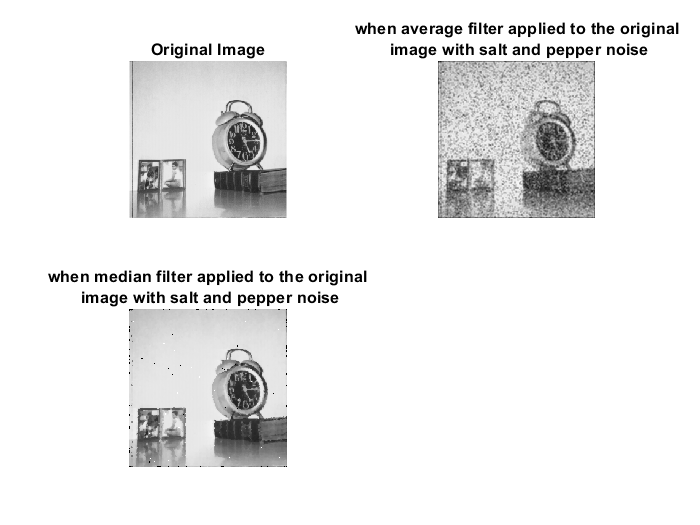

x_imp=imnoise(x,'salt & pepper',0.2);
x_imp_augmented=zeros(258,258);
x_imp_augmented(2:257,2:257)=x_imp;
[N1,N2]=size(x_imp_augmented);

x_average=zeros(256,256);
x_median=zeros(256,256);
for i=1:N1-2
    for j=1:N2-2
        kernel=x_imp_augmented(i:i+2,j:j+2);
        kernel_average=mean(kernel,'all');
        kernel_median=median(kernel,'all');
        x_average(i+1,j+1)=kernel_average;
        x_median(i+1,j+1)=kernel_median;
    end
      
end
x_average=uint8(x_average(2:257,2:257));
x_median=uint8(x_median(2:257,2:257));

figure();
subplot(2,2,1);
imshow(x);
title("Original Image");
subplot(2,2,2);
imshow(x_average);
title({"when average filter applied to the original";" image with salt and pepper noise"})
subplot(2,2,3);
imshow(x_median);
title({"when median filter applied to the original";" image with salt and pepper noise"})

3) Στην εικόνα clock.tiff προσθέστε λευκό Gaussian θόρυβο μηδενικής μέσης τιμής και τέτοιας διασποράς ώστε η τελική εικόνα να έχει 15 dB, καθώς και κρουστικό θόρυβο σε ποσοστό 20%. Γίνονται δοκιμές ώστε να βρεθεί πειραματικά ποιά είναι η πιό αποδοτική σειρά για να εφαρμοστούν τα φίλτρα.

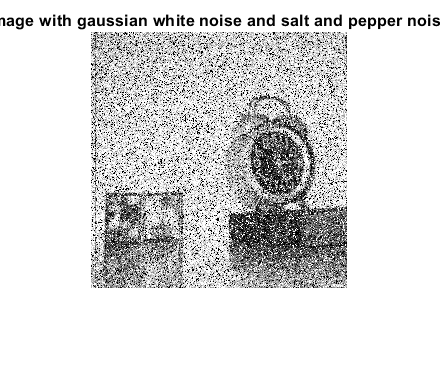

x_white_imp=imnoise(x_with_noise,'salt & pepper',0.2);
figure();
imshow(x_white_imp);
title("Image with gaussian white noise and salt and pepper noise");

x_white_imp_augmented=zeros(258,258);
x_white_imp_augmented(2:257,2:257)=x_white_imp;
[N1,N2]=size(x_white_imp_augmented);

x_average=zeros(256,256);
for i=1:N1-2
    for j=1:N2-2
        kernel=x_white_imp_augmented(i:i+2,j:j+2);
        kernel_average=mean(kernel,'all');
        x_white_imp_average(i+1,j+1)=kernel_average;
        kernel_median=median(kernel,"all");
        x_white_imp_median(i+1,j+1)=kernel_median;
    end
      
end



x_white_imp_average=uint8(x_white_imp_average(2:257,2:257));

x_white_imp_average_augmented=zeros(258,258);
x_white_imp_average_augmented(2:257,2:257)=x_white_imp_average;
[N1,N2]=size(x_white_imp_average_augmented);

x_average=zeros(256,256);
for i=1:N1-2
    for j=1:N2-2
        kernel=x_white_imp_average_augmented(i:i+2,j:j+2);
        kernel_median=median(kernel,"all");
        x_white_imp_average_median(i+1,j+1)=kernel_median;
    end
      
end
x_white_imp_average_median=uint8(x_white_imp_average_median(2:257,2:257));




x_white_imp_median=uint8(x_white_imp_median(2:257,2:257));

x_white_imp_median_augmented=zeros(258,258);
x_white_imp_median_augmented(2:257,2:257)=x_white_imp_median;
[N1,N2]=size(x_white_imp_median_augmented);

x_median=zeros(256,256);
for i=1:N1-2
    for j=1:N2-2
        kernel=x_white_imp_median_augmented(i:i+2,j:j+2);
        kernel_average=mean(kernel,"all");
        x_white_imp_median_average(i+1,j+1)=kernel_average;
    end
      
end
x_white_imp_median_average=uint8(x_white_imp_median_average(2:257,2:257));

 

4) Παρατηρείται ότι η χρήση μου Median Filter εξάγει καλύτερα αποτελέσματα και είναι λογικό αφού οι ακραίες τιμές που εισάγονται μέσω του κρουστικού θορύβου επηρρεάζουν τον υπολογισμό του μέσου όρου

-  Όπως και το mean φίλτρο, το median φίλτρο εξετάζει κάθε pixel στην εικόνα με τη σειρά του και κοιτάζει τους γείτονές του για να αποφασίσει εάν είναι ή όχι αντιπροσωπευτικό του περιβάλλοντός του. Αντί να αντικαθιστά απλώς την τιμή pixel με τη μέση τιμή γειτονικών εικονοστοιχείων, την αντικαθιστά με τη διάμεση τιμή αυτών των τιμών. Η διάμεση τιμή υπολογίζεται πρώτα ταξινομώντας όλες τις τιμές pixel από τη γειτονιά σε αριθμητική σειρά και στη συνέχεια αντικαθιστώντας το pixel που εξετάζεται με την τιμή του μεσαίου pixel. (Εάν η υπό εξέταση περιοχή περιέχει έναν ζυγό αριθμό εικονοστοιχείων, χρησιμοποιείται ο μέσος όρος των δύο τιμών μεσαίου εικονοστοιχείου.) 

- Σε γενικές γραμμές, το median φίλτρο επιτρέπει τη διέλευση πολλών λεπτομερειών υψηλής χωρικής συχνότητας, ενώ παραμένει πολύ αποτελεσματικό στην απομάκρυνση του θορύβου σε εικόνες όπου έχουν πραγματοποιηθεί λιγότερα από τα μισά pixel σε μια περιοχή εξομάλυνσης. (Ως συνέπεια αυτού, το μέσο φιλτράρισμα μπορεί να είναι λιγότερο αποτελεσματικό στην απομάκρυνση του θορύβου από εικόνες που έχουν καταστραφεί με θόρυβο Gaussian.)

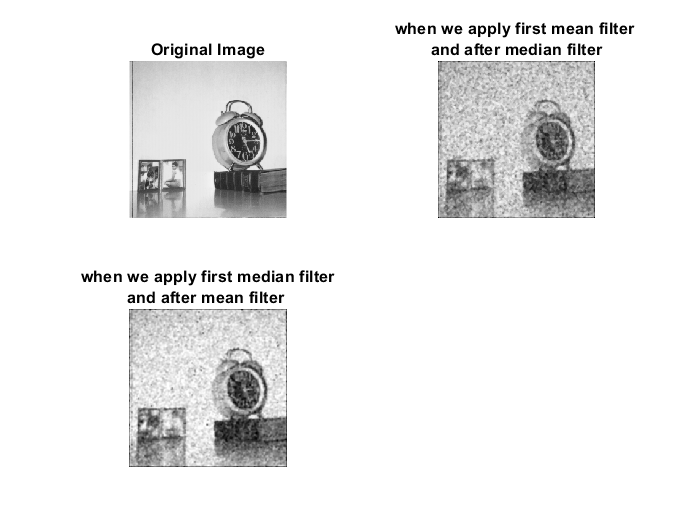


figure();
subplot(2,2,1);
imshow(x);
title("Original Image");
subplot(2,2,2);
imshow(x_white_imp_average_median);
title({"when we apply first mean filter ";"and after median filter"})
subplot(2,2,3);
imshow(x_white_imp_median_average);
title({"when we apply first median filter";"and after mean filter "})